% clear;clc;close all;

% %轨迹识别，后期可优化
% %t = 0:0.05:2;
% %qz = [0 0 0 0 0];
% %qn = [pi/2 -pi/2 pi/6 pi/12 pi/4];
% %[q,qd,qdd] = jtraj(qz,qn,t);
% %Ti = MyRobot.fkine(qz);
% %Tf = MyRobot.fkine(qn);
% 
% %plot(MyRobot,q,'trail','b-')

% %正式
% 
% %将URDF模型导入MATLAB
% %clc;
% %myrobot = importrobot('xxxxxx.urdf');
% %show(myrobot);
% 

% %建立机械臂模型
% d = [0 0 0 0 0];
% a = [0 1000 1000 1000 0];
% alpha = [-pi/2 0 0 pi/2 0];
% %设置初值
% L(1) = Link([0 d(1) a(1) alpha(1)],'modified');
% L(2) = Link([0 d(2) a(2) alpha(2)],'offset',pi/2,'modified');
% L(3) = Link([0 d(3) a(3) alpha(3)],'offset',-pi/2,'modified');
% L(4) = Link([0 d(4) a(4) alpha(4)],'offset',pi/2,'modified');
% L(5) = Link([0 d(5) a(5) alpha(5)],'modified');
% 
% %定义关节范围
% L(1).qlim = [-150,150]*pi/180;
% L(2).qlim = [-150,150]*pi/180;
% L(3).qlim = [-150,150]*pi/180;
% L(4),qlim = [-150,150]*pi/180;
% L(5).qlim = [-150,150]*pi/180;
% 
% robot = SerialLink(L,'name','robot');
% %定义基坐标和工具坐标
% MyRobot.base = transl(0,0,0);
% MyRobot.tool = transl(0,0,100);
% 
% robot.plot([0 0 0 0 0]);
% 
% %计算位姿矩阵
% syms th1 th2 th3 th4 th5;
% syms a1 a2 a3 a4 a5;
% syms d1 d2 d3 d4 d5;
% syms alp1 alp2 alp3 alp4 alp5;
% 
% L(1) = Link([0 d1 a1 alp1 th1],'modified');
% L(2) = Link([0 d2 a2 alp2 th2],'modified');
% L(3) = Link([0 d3 a3 alp3 th3],'modified');
% L(4) = Link([0 d4 a4 alp4 th4],'modified');
% L(5) = Link([0 d5 a5 alp5 th5],'modified');
% 
% [d1,d2,d3,d4,d5] = deal(0);
% [alp1,alp2,alp3,alp4,alp5] = deal(alpha(1),alpha(2),alpha(3),alpha(4),alpha(5));
% a1 = 0;
% 
% L(1) = Link([th1 d1 a1 alp1 0],'modified');
% L(2) = Link([th2 d2 a2 alp2 0],'modified');
% L(3) = Link([th3 d3 a3 alp3 0],'modified');
% L(4) = Link([th4 d4 a4 alp4 0],'modified');
% L(5) = Link([th5 d5 a5 alp5 0],'modified');
% 
% robot = SerialLink(L,'name','robot');
% 
% %计算总转换矩阵
% %正运动学
% T = L(1).A(th1) * L(2).A(th2) * L(3).A(th3) * L(4).A(th4) * L(5).A(th5);
% T = simplify(T)

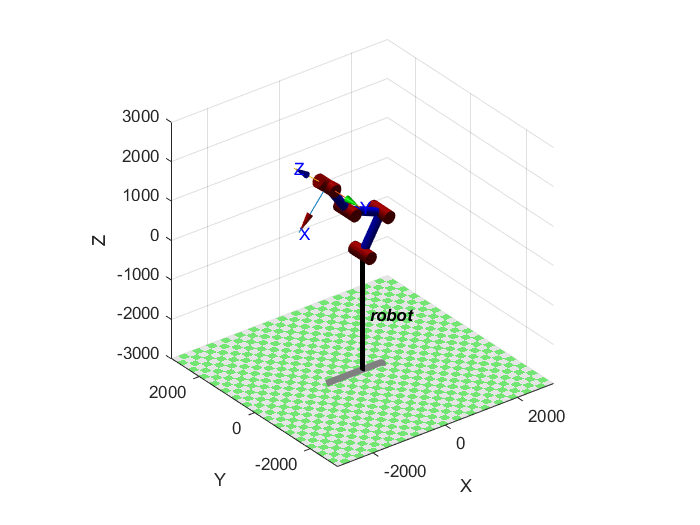

%导入模型
mdl_5dof;
%采用关节空间轨迹规划
%给出关节角度
%前六个为手臂移动后读到的值，后六个为初始值
syms x1 x2 x3 x4 x5 x6 x11 x22 x33 x44 x55 x66;
syms y1 y2 y3 y4 y5 y6 y11 y22 y33 y44 y55 y66;
syms z1 z2 z3 z4 z5 z6 z11 z22 z33 z44 z55 z66;
syms a1 a2 a3 a4 a5 a6 a11 a22 a33 a44 a55 a66;
%代入关节角度

si = [20 50 -30 -10 -25]*pi/180;
sf = [70 10 -60 30 -50]*pi/180;

t = 0:0.1:4;
T1 = robot.fkine(si);
T2 = robot.fkine(sf);
q1 = robot.ikine(T1,'mask',[1 1 1 1 1 0]);
q2 = robot.ikine(T2,'mask',[1 1 1 1 1 0],'q0',q1);

[q,qt,qtt] = jtraj(q1,q2,t);

robot.plot(q);

%mdl_Dyn_5dof;
% while(true)
%     t = 0:0.1:4;
%     T1 = robot.fkine([20 50 -30 -25 -10]*pi/180);
%     %机械爪不动端:
%     dx = x66-x55;
%     %dy = y66-y55; 暂时未用到
%     dz = z66-z55;
%     %读入xyz坐标---从Python读入（下面是我临时输入的）
%     x1 = 0;x2=1000;x3=1000;x4=1000;x5=1000;
%     y1=0;y2=1000;y3=1000;y4=1000;y5=1000;
%     z1=0;z2=1000;z3=1000;z4=1000;z5=1000;
%     %[y1,y2,y3,y4,y5] = [0 1000 1000 1000 1000];
%     %[z1,z2,z3,z4,z5] = [0 1000 1000 1000 1000];
%     %T2 = transl(x1,y1,z1)*transl(x2,y2,z2)*transl(x3,y3,z3)*transl(x4,y4,z4)*transl(x5,y5,z5);
%     
%     a1 = atan2((y4-y1)/(x4-x1));
%     a2 = atan2((x3-x2)/(z3-z2));
%     a3 = atan2((x4-x3)/(z4-z3));
%     a4 = atan2((y6-y4)/(z6-z4));
%     a5 = atan2((z6-z5-dz)/(x6-x5-dx));
%     
%     T2 = robot.fkine([a1 a2 a3 a4 a5]*pi/180);
%     
%     q1 = robot.ikine(T1,'mask',[1 1 1 1 1 0]);
%     q2 = robot.ikine(T2,'mask',[1 1 1 1 1 0],'q0',q1);
% 
%     [q,qt,qtt] = jtraj(q1,q2,t);
% 
%     robot.plot(q);
% 
%    
%     t = MDH_Dyn(robot,q,qt,qtt)
% 
%     T2 = T1;
% end

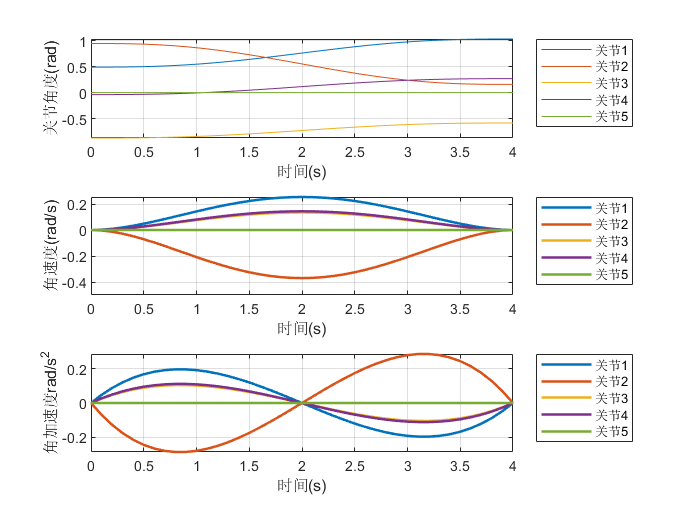

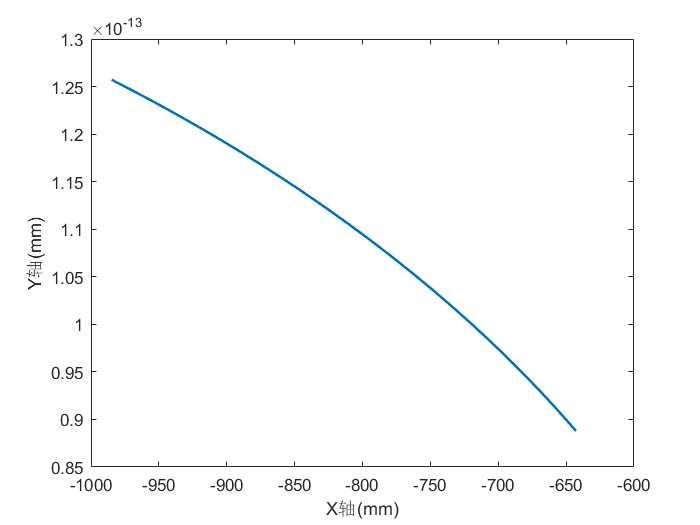

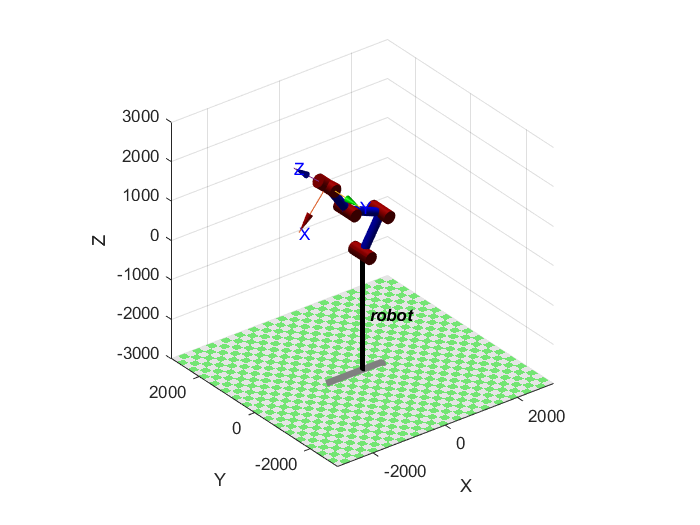

%画图
figure('name','关节随时间变化');
subplot(3,1,1);
plot(t,q);
grid on;
xlabel('时间(s)');ylabel('关节角度(rad)');
legend('关节1','关节2','关节3','关节4','关节5','location','northeastoutside');

%绘制关节角速度随时间的变化
subplot(3,1,2);
plot(t, qt,'LineWidth',1.5) 
grid on;
xlabel('时间(s)');ylabel('角速度(rad/s)');
legend('关节1','关节2','关节3','关节4','关节5','location','northeastoutside');

%绘制关节角加速度随时间的变化
subplot(3,1,3);
plot(t,qtt,'LineWidth',1.5);
grid on;
xlabel('时间(s)');ylabel('角加速度rad/s^2');
legend('关节1','关节2','关节3','关节4','关节5','location','northeastoutside');

%末端执行器轨迹
figure();
T = robot.fkine(q); %得到笛卡尔轨迹
p = transl(T); %轨迹的位移部分
plot(p(:,1),p(:,2),'LineWidth',1.5);
xlabel('X轴(mm)');ylabel('Y轴(mm)')
%title('末端执行器轨迹(x-y视图)')

%带轨迹标记的运动过程
figure();
plot3(p(:,1),p(:,2),p(:,3),'LineWidth',1.5);
robot.plot(q);

%mdl_Dyn_5dof;
%t = MDH_Dyn(robot,q,qt,qtt)


